# **This is the title**

Maxwell's Equations:


$$\begin{array}{l}
\vec{\nabla} \cdot \vec{E} =\rho /\epsilon_0 \;\;\;\;\;\;\;\;\;\;\vec{\nabla} \cdot \vec{B} =0\\
\vec{\nabla} \times \vec{E} =-\frac{\partial \vec{B} }{\partial t}\;\;\;\;\;\;\vec{\nabla} \times \vec{B} =\mu_0 \left(\vec{J} +\epsilon_0 \frac{\partial \vec{E} }{\partial t}\right)
\end{array}$$
    

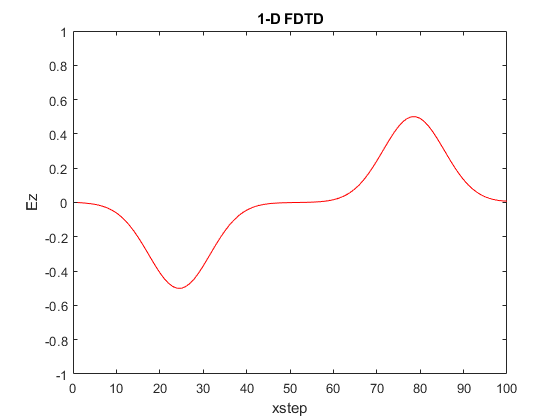

tsteps = 500;
xsteps = 100;
imp0 = 377;     % impedance of free space
%initialize the magnetic and electric field arrays
Hy = zeros(1,xsteps);
Ez = zeros(1,xsteps);
% time step loop
for qq = 1:tsteps  
    % update the magnetic field
    for ii = 1:(xsteps-1)
        Hy(ii) = Hy(ii) + (Ez(ii+1) - Ez(ii))/imp0;
    end
    %update the electric field
    for ii = 2:xsteps
        Ez(ii) = Ez(ii) + (Hy(ii) - Hy(ii-1))*imp0;
    end
    % first node is source of Gaussian pulse
    Ez(50) = Ez(50) + exp(-(qq-30)^2/100);
    if mod(qq,2) == 0
        %plot(1:xsteps,Hy*imp0,'b');
        %hold on;
        plot(1:xsteps,Ez,'r');
        title("1-D FDTD");
        xlabel("xstep");
        ylabel("Ez");
        axis([0 xsteps -1 1]);
        %hold off;
        drawnow;
    end
end